# Chan object methods

pathstr1 = fileparts(which('WaveformChan.m'));

S = load(fullfile(pathstr1,'kjx127a01@0-20_double.mat'));

finames = fieldnames(S);

S1 = S.(finames{1});

obj1 = Chan.constructChan(S1);
class(obj1)

ans = EventChan

Let's have a look at properties of EventChan

properties(obj1)


Properties for class EventChan:

    Data
    ISI
    InstantRate
    TimeStamps
    FiringRate
    NSpikes
    Stats
    ChanTitle
    DataUnit
    Start
    SRate
    Header
    Path
    ChanNumber
    Length
    SInterval
    MaxTime
    TimeUnit



Let's have a look at methods of EventChan

methods(obj1)


Methods for class EventChan:

EventChan                 
chan2struct               
chan2ts                   
eq                        
extractTime               
getChanInfo               
getSpikeInfo              
max                       
mean                      
median                    
min                       
mode                      
neurospec_EveEve_sp2_m1   
neurospec_WavEve_sp2a_m1  
nextSpike                 
plot                      
plotCV2hist               
plotCV2vsISIpair          
plotCorr                  
plotISIbefaft             
plotISIhist               
plotInstantRate           
plotMeanFiringRate        
plotPSTH                  
plotPhaseHist             
plotRateHistogram         
plotTriggered             
plus                      
prevSpike                 
resample                  
std                       
sum                       
testProperties            
time                      
var                       
vertcat                 

## `plot`

ans =     figh: [1x1 Figure]
     axh: [1x1 Axes]
      l1: [1x1 Line]
      l2: [7x1 Line]


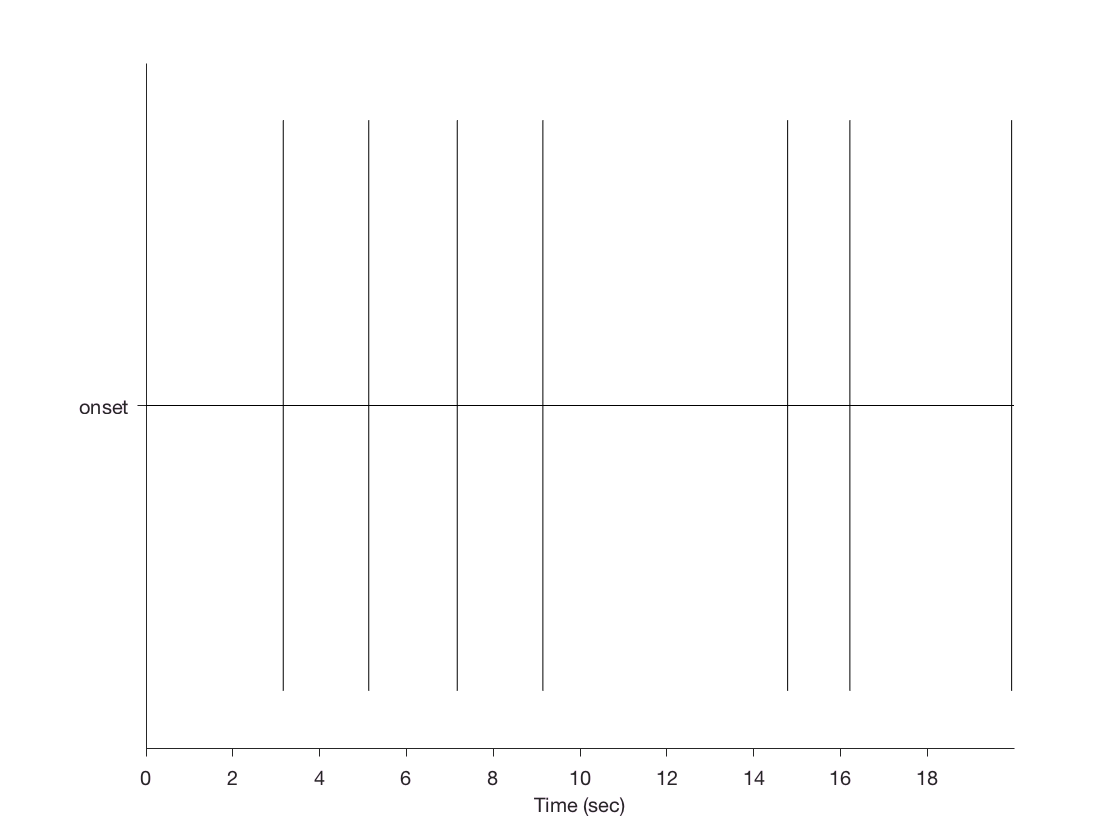

%  h = plot(obj)
%  h = plot(obj, 'Param', Value)
%  h = plot(obj, axh, 'Param', Value, ...)

obj1.plot